**Creación mecanismo:**

syms L;
L = 3

L = 3

%Offset signigica la posición de Home
%Links = ([theta d a alpha sigma (tipo de articulación) mHD Offset])
L1 = Link ('revolute', 'd', 0, 'a', 0, 'alpha', -pi/2 , 'offset', 0); %Eslabón 1
L2 = Link ('revolute', 'd', 0, 'a', L, 'alpha', 0 , 'offset', 0); %Eslabón 1
L3 = Link ('revolute', 'd' , 0, 'a',L, 'alpha', 0, 'offset', 0);
Ejercicio1 = SerialLink([L1 L2 L3]', 'name', 'Ejercicio1')

 
Ejercicio1 = 
 
Ejercicio1:: 3 axis, RRR, stdDH, slowRNE                         
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|    -1.5708|          0|
|  2|         q2|          0|          3|          0|          0|
|  3|         q3|          0|          3|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


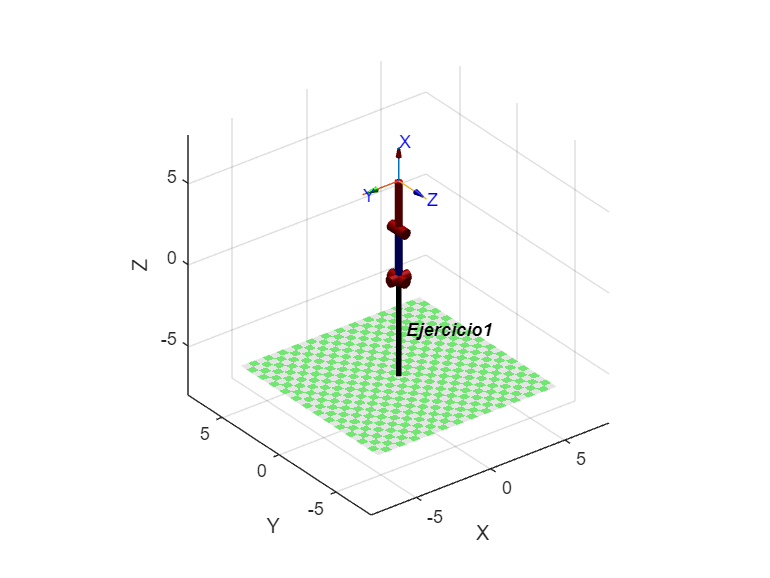

Ejercicio1.base = [0 0 1 0 ; 0 -1 0 0; 1 0 0 0; 0 0 0 1];
Ejercicio1.plot([0 0 0])

xlim([-8 8])
ylim([-8 8])
zlim([-8 8])

**Configuración del plot**

set(gca, 'ZDir', 'reverse'); % Invertir el eje Z
xlim([-8 8])
ylim([-8 8])
zlim([0 8])

view([3.72 6.06])

### **Posiciones**

**Pierna Flexionada:**

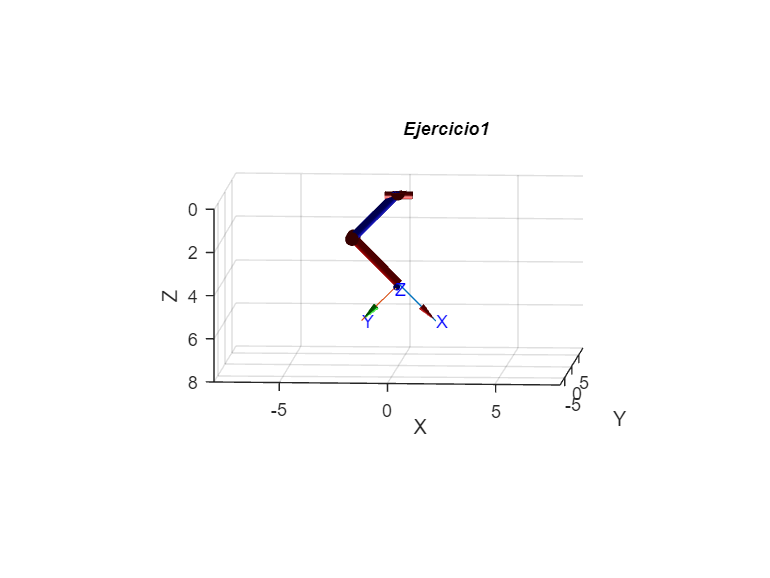

%Pierna flexionada
Ejercicio1.plot([0 pi/4 -pi/2])

**Caminar**

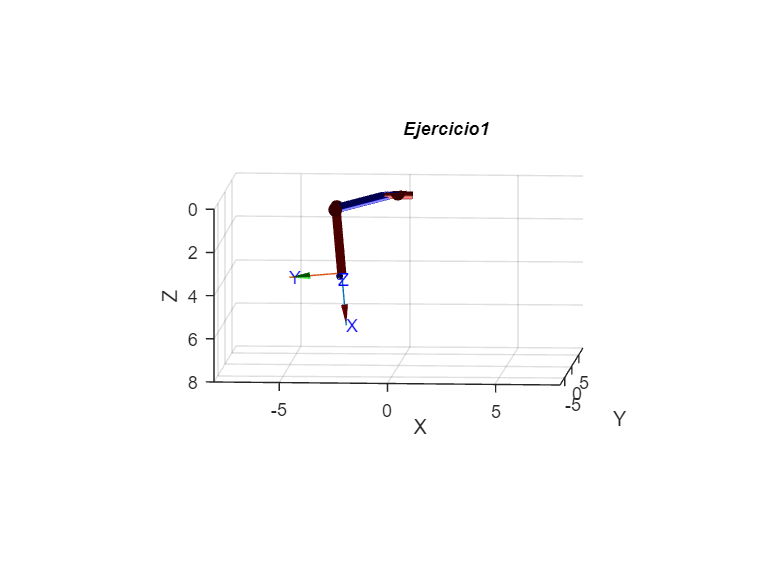

%CAMINAR
%Hacia atrás
Ejercicio1.plot([0 deg2rad(75) deg2rad(-80)])

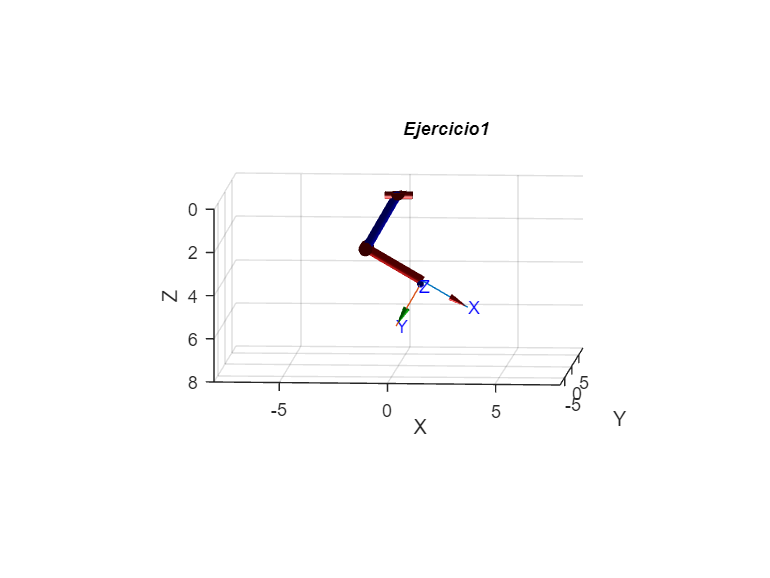

%Hacia adelante
Ejercicio1.plot([0 deg2rad(30) deg2rad(-90)])

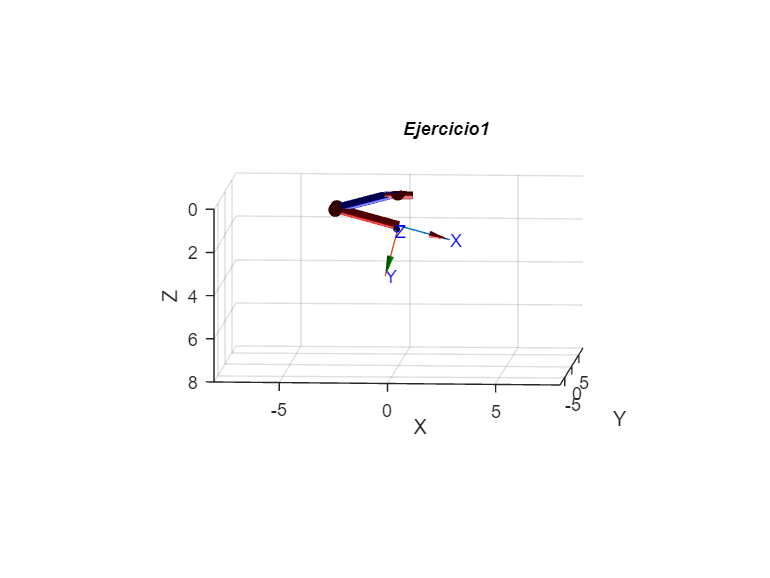

%Agachado
Ejercicio1.plot([0 deg2rad(75) deg2rad(-150)])

## **Movimientos**

### **Extensión y flexión**

**Movimiento de flexión**

ang2 = 0:0.05:pi/4;
ang3 = 0:-0.1:-pi/2;

**Movimiento de extensión**

ang2 = pi/4:-0.05:0;
ang3= -pi/2:0.1:0;

### **Caminar**

**Movimiento hacia atrás (primera vez) (75, -80)**

ang2 = 0:0.1:deg2rad(75);
ang3 = 0:-0.1:deg2rad(-80);

**Movimiento hacia adelante (30, -90)**

ang2 = deg2rad(75):-0.1:deg2rad(30);
ang3 = deg2rad(-80):-0.024:deg2rad(-90);

Movimiento hacia atrás (segunda vez)

ang2 = deg2rad(30):0.1:deg2rad(75);
ang3 = deg2rad(-90):0.024:deg2rad(-80);

**FUNCIÓN**

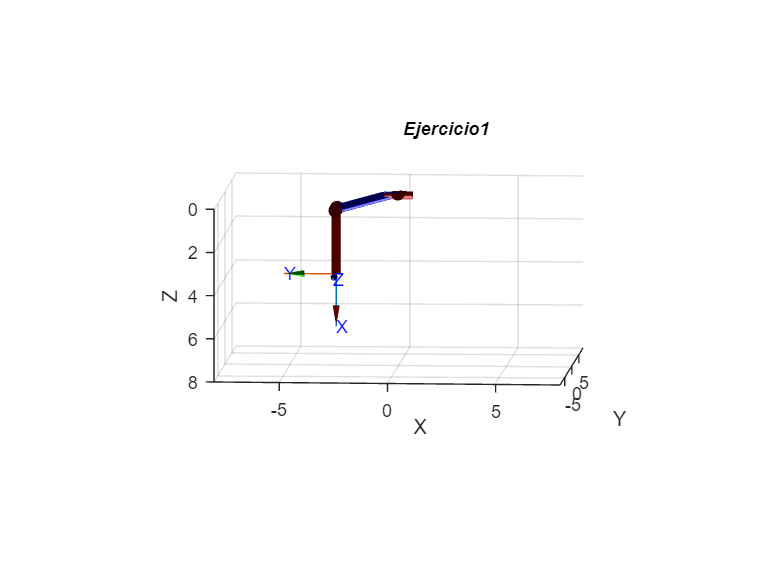

%------------------
%Configuración del plot
set(gca, 'ZDir', 'reverse'); % Invertir el eje Z
xlim([-8 8])
ylim([-8 8])
zlim([0 8])
view([3.72 6.06])

ang2 = 0:0.1:deg2rad(75);
ang3 = 0:-0.1:deg2rad(-80);
for i = 1:length(ang3)
    ang2_actual = ang2(i);
    ang3_actual = ang3(i);
         
    % Mover el robot a la configuración actual
    Ejercicio1.plot([0, ang2_actual, ang3_actual]);
         
    % Pausa para la animación
    pause(0.1)
end